Question 1 a

p = @(x) polyval([1 0 0 0 0 -1], x);
X = linspace(-2, 2, 6);
Y = p(X);
x = -1.7;
err = abs(p(x) - linterp_bary(X, Y, x))

err = 1.7764e-15

Question 1 b

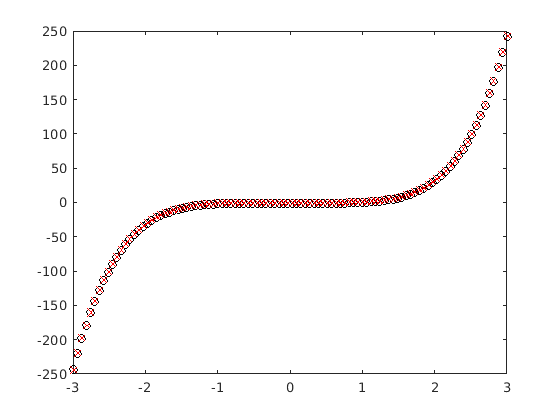

x = linspace(min(X) - 1, max(X) + 1, 100);
plot(x, p(x), 'ko', x, linterp_bary(X,Y,x), 'rx')

function y = linterp_bary(X,Y,x)
    y = 0;
    y1 = 0;
    y2 = 0;
    for i = 1:numel(X)
        w = 1;
        for j = 1:numel(X)
            if i ~= j
                w = w * (X(i) - X(j));
            end
        end
        w = 1/w;
        y1 = y1 + Y(i).*(w./(x-X(i)));
        y2 = y2 + (w./(x-X(i)));
    end
    y = y1 ./ y2;
end